# Feedback Control of a DC Motor

Dr. Matthew Nokleby, Wayne State University. ECE 4330, Fall 2018.

Let's use what we've learned about Laplace transform analysis of feedback systems in order to build a simple controller for a DC motor.

A DC motor is a simple device: apply an input voltage and watch the rotor spin around. We'll take the input voltage as the input signal f(t), and the angular position of the rotor (measured in radians) as the output signal y(t).

In controls, we want to be able to apply an input signal f(t) as a *command* or a *request*, and we want the output signal y(t) to track the input as closely as possible. Imagine the motor turns a telescope; as a celestial object moves, we'll want rotate the telescope to keep the object in view. This takes a little finesse!

The transfer function of a DC motor has the form $H(s) = \frac{1}{s(s+c)}$. The $1/s$ term results in the motor *velocity* being equal to the input voltage. The $1/(s+c)$ results in a transient; the larger $c$, the quicker the motor velocity can change when $x(t)$ changes.

It's clear that $y(t)$ isn't going to track $x(t)$ on its own; this system isn't even stable!

Let's see what happens when we apply a *step* input. This input is our request; we want y(t) to track the height of the step function as closely as possible.

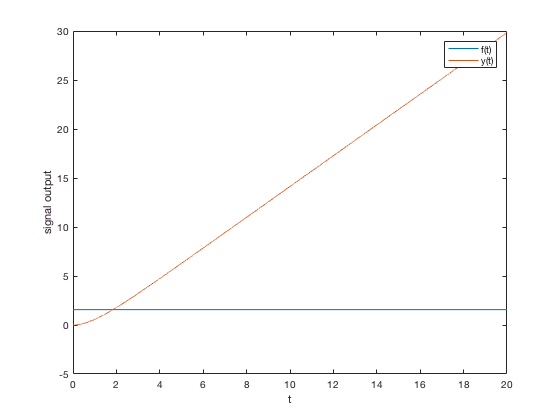

c = 1;
tValues = 0:10^-3:20;

%lsim parameters
a = [1 c 0];
b = [1];

%build the input signal
alpha = pi/2; %
f = alpha*ones(length(tValues),1);

y = lsim(b,a,f,tValues);

close all;
plot(tValues,f,tValues,y);
xlabel('t');
ylabel('signal output');
legend('x(t)','y(t)');

Because of the integrator term 1/s, this system is unstable as-is! If we apply a constant voltage, the motor is just going to spin around mindlessly at a constant rate.

To fix this, we'll choose a very simple form of feedback control called a *proportional* controller. Instead of inputting our control signal to the system naively, we will input a signal that is proprotional to the *error* e(t) = x(t) - y(t). If K is the proportionality constant, the resulting system has the transfer function  $T(s) = \frac{K H(s)}{1+K H(s)}  = \frac{K}{s(s+c) + K}$. Depending on our choice of K, we can make the resulting system stable, and we can make the output track the input with varying degrees of accuracy.

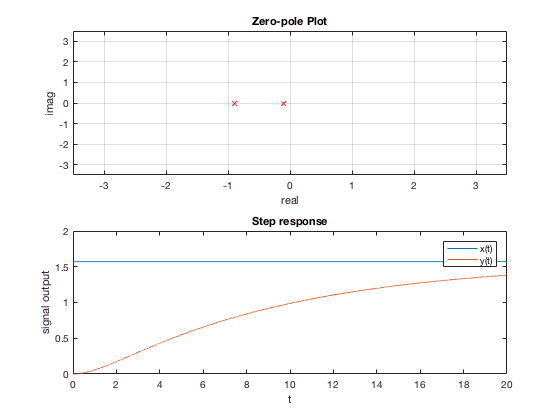

K = 0.1; %we'll tweak this to see how we go!

tValues = 0:10^-3:20;
%new lsim parameters
a = [1 c K];
b = [K];

%Where are the poles of the feedback system?
poles = roots(a);

%build the input signal
alpha = pi/2;
f = alpha*ones(length(tValues),1);

y = lsim(b,a,f,tValues);

close all;
subplot(2,1,1);
plot(real(poles),imag(poles),'rx');
grid;
axis([-3.5 3.5 -3.5 3.5]);
title('Zero-pole Plot');
xlabel('real');
ylabel('imag');

subplot(2,1,2);
plot(tValues,f,tValues,y);
xlabel('t');
ylabel('signal output');
legend('x(t)','y(t)');
title('Step response');

For small $K$, we get two real poles. As we increase $K$, the poles move. The rightmost pole moves further away from the jw-axis,  and the system responds faster. At a specific value of $K$, which depends on $c$, the poles lie on top of each other, and we say the system is *critically damped*. If we increase $K$ beyond this point, we will introduce an increasing imaginary component to the poles. The system will overshoot and exhibit ringing, but it won't settle to the steady-state value any more quickly. On the other hand, the system *does* respond a bit faster. It's standard to choose $K$ to be critically damped, but if the rise time of the system is important enough, a control engineer might decide that it's worth a bit of overshoot and ringing.

One last thing to try: What happens if we change the input signal as we go? Will our feedback system track the changes?

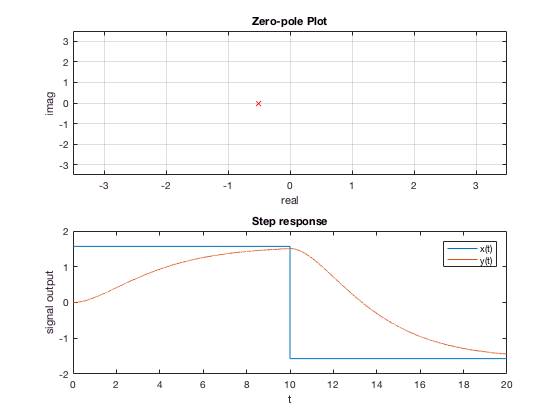

K = 0.25;

tValues = 0:10^-3:20;
%new lsim parameters
a = [1 c K];
b = [K];

%Where are the poles of the feedback system?
poles = roots(a);

%build the input to change halfway through
alpha1 = pi/2;
alpha2 = -pi/2;
f = alpha*ones(length(tValues),1);
f(round(length(tValues)/2):end) = alpha2;

y = lsim(b,a,f,tValues);

close all;
subplot(2,1,1);
plot(real(poles),imag(poles),'rx');
grid;
axis([-3.5 3.5 -3.5 3.5]);
title('Zero-pole Plot');
xlabel('real');
ylabel('imag');

subplot(2,1,2);
plot(tValues,f,tValues,y);
xlabel('t');
ylabel('signal output');
legend('x(t)','y(t)');
title('Step response');

Sure enough, it tracks our changes. However, this isn't a great controller. We could do better by adding an *integrator* or *derivative* term to the feedback input. So-called *PID* controllers will be a major object of study when you take controls!